# Hailing CNS Merge

## merge round 1 dots and rotate

input_path = 'F:/2021-02-10-Hailing-Mouse-CNS/output/max/';
input_dim = [1496 1496 30 4];


data_dirs = dir(fullfile(input_path, "tile*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);

Ndirs = numel(data_dirs);

rotation_degress = -90; 


upd = textprogressbar(Ndirs, 'updatestep', 1);

Completed [                    ]   0% --:--:--


% Iterate through each position folder
for p=1:Ndirs
    
    curr_data_dir = data_dirs{p};
    
    % rotate round 1 merge
    curr_file_path = fullfile(input_path, "round1_merged", sprintf("%s.tif", curr_data_dir));
    curr_out_path = fullfile(input_path, "round1_merged_rotated");
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
    
    curr_rd1_max_out_path = fullfile(input_path, "round1_max_rotated");
    if ~exist(curr_rd1_max_out_path, 'dir')
        mkdir(curr_rd1_max_out_path)
    end
    
    curr_img = new_LoadMultipageTiff(curr_file_path, 'uint8', 'uint8', false);
    curr_img = imrotate(curr_img, rotation_degress); % rotate the image clockwise by 90 degrees
    curr_img = MinMax_uint8(curr_img);
    curr_max = max(curr_img, [], 3);
    curr_max = imadjust(curr_max);
    
%     curr_fname = fullfile(curr_out_path, sprintf("%s.tif", curr_data_dir));
%     if exist(curr_fname, 'file') == 2
%         delete(curr_fname);
%     end
%     
%     for j=1:input_dim(3)
%         imwrite(curr_img(:,:,j), curr_fname, 'writemode', 'append');        
%     end
    
    imwrite(curr_max, fullfile(curr_rd1_max_out_path, sprintf("%s.tif", curr_data_dir)));
    
    % rotate round 1 dapi
    curr_dapi_folder = fullfile("F:/2021-02-10-Hailing-Mouse-CNS/round1/", curr_data_dir);
    curr_files = dir(fullfile(curr_dapi_folder, "*.tif"));
    curr_dapi_file = fullfile(curr_files(5).folder, curr_files(5).name);
    curr_out_path = fullfile(input_path, "dapi_rotated");
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
    
    curr_max_out_path = fullfile(input_path, "dapi_max_rotated");
    if ~exist(curr_max_out_path, 'dir')
        mkdir(curr_max_out_path)
    end
    
    
    curr_img = new_LoadMultipageTiff(curr_dapi_file, 'uint8', 'uint8', false);
    curr_img = imrotate(curr_img, rotation_degress); % rotate the image clockwise by 90 degrees
    curr_img = MinMax_uint8(curr_img);
    curr_max = max(curr_img, [], 3);
    curr_max = imadjust(curr_max);
    
%     curr_fname = fullfile(curr_out_path, sprintf("%s.tif", curr_data_dir));
%     if exist(curr_fname, 'file') == 2
%         delete(curr_fname);
%     end
%     
%     for j=1:input_dim(3)
%         imwrite(curr_img(:,:,j), curr_fname, 'writemode', 'append');        
%     end
    
    imwrite(curr_max, fullfile(curr_max_out_path, sprintf("%s.tif", curr_data_dir)));
    
    upd(p);
end

Completed [====================] Done. [988 seconds]


## Stitch images with Fiji

% merge dots 
stitch_file = fullfile(input_path, "round1_merged_rotated/", "TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y' 'z'};
TileConfiguration.x = int32(TileConfiguration.x);
TileConfiguration.y = int32(TileConfiguration.y);

head(TileConfiguration, 5)

ans = 5×4 table
    tile     x      y    z
    ____    ____    _    _

      1        0    0    0
     27     1346    0    0
     53     2692    0    0
     79     4038    0    0
    105     5384    0    0



%% Clear temporary variables
clear opts

## modify each tile

trim_range = 1:30;
global_offsets = int32(abs([min(TileConfiguration.x); min(TileConfiguration.y)]));

% load stitched dapi image
dapi_file = fullfile(input_path, "stitched_images", 'dapi.tif')

dapi_file = "F:\2021-02-10-Hailing-Mouse-CNS\output\max\stitched_images\dapi.tif"

dapi_img = imread_big(dapi_file);
dapi_max = max(dapi_img, [], 3);


merged_points = int32([]);
merged_reads = {};
merged_region = [];

for r=1:size(TileConfiguration,1)
% for r=1:40
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y, z] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("tile_%d", tile)
    curr_dot_file = fullfile(input_path, curr_position_dir, "goodPoints_max3d.mat");
    load(curr_dot_file);
    
    if ~isempty(goodReads)
         if rotation_degress == -90
            % rotate 90 c
            temp = goodSpots;
            goodSpots(:, 2) = temp(:, 1);
            goodSpots(:, 1) = 1497 - temp(:, 2);
        elseif rotation_degress == -180
            % rotate 180 c
            temp = goodSpots;
            goodSpots(:, 1) = 1497 - temp(:, 1);
            goodSpots(:, 2) = 1497 - temp(:, 2);
        end
        
        % trim along z
        toKeep = ismember(goodSpots(:,3), trim_range);
        goodSpots = goodSpots(toKeep, :);
        goodReads = goodReads(toKeep);
        
        % add offset
%         if x < 0
%             x = 0;
%         end
        goodSpots = int32(goodSpots) + int32([x y z]);
        goodSpots(:, 1) = goodSpots(:, 1) + global_offsets(1); 
        goodSpots(:, 2) = goodSpots(:, 2) + global_offsets(2); 
            
        % construct dots region
        current_min = min(goodSpots, [], 1);
        current_max = max(goodSpots, [], 1);
        if current_max(1) > size(dapi_max, 2)
            fprintf("1")
            current_max(1) = size(dapi_max, 2);
            toKeep = goodSpots(:, 1) <= current_max(1);
            goodSpots = goodSpots(toKeep, :);
            goodReads = goodReads(toKeep);
        
        else if current_max(2) > size(dapi_max, 1)
                fprintf("2")
                current_max(2) = size(dapi_max, 1);   
             
                toKeep = goodSpots(:, 2) <= current_max(2);
                goodSpots = goodSpots(toKeep, :);
                goodReads = goodReads(toKeep);
            
        end
        end
        current_region = zeros(size(dapi_max));
        current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
        
        % merge dots 
        if isempty(merged_region)
            merged_region = current_region;
        else
            current_overlap = merged_region & current_region;
            merged_region = merged_region | current_region;
            current_region = current_region - current_overlap; 
            
            temp_cell = num2cell(goodSpots, 2); 
            current_lindex = cellfun(@(x) sub2ind(size(dapi_img), x(2), x(1)), temp_cell);
            current_logical = logical(current_region(current_lindex));
            goodSpots = goodSpots(current_logical, :);
            goodReads = goodReads(current_logical);
        end
        
        % save current 
        merged_points = [merged_points; goodSpots];
        merged_reads = [merged_reads; goodReads];
    end
end

curr_position_dir = "tile_1"

curr_position_dir = "tile_27"

curr_position_dir = "tile_53"

curr_position_dir = "tile_79"

curr_position_dir = "tile_105"

curr_position_dir = "tile_131"

curr_position_dir = "tile_157"

curr_position_dir = "tile_183"

curr_position_dir = "tile_209"

curr_position_dir = "tile_235"

curr_position_dir = "tile_261"

curr_position_dir = "tile_287"

curr_position_dir = "tile_313"

curr_position_dir = "tile_339"

curr_position_dir = "tile_365"

curr_position_dir = "tile_391"

curr_position_dir = "tile_417"

curr_position_dir = "tile_443"

curr_position_dir = "tile_469"

curr_position_dir = "tile_2"

curr_position_dir = "tile_28"

curr_position_dir = "tile_54"

curr_position_dir = "tile_80"

curr_position_dir = "tile_106"

curr_position_dir = "tile_132"

curr_position_dir = "tile_158"

curr_position_dir = "tile_184"

curr_position_dir = "tile_210"

curr_position_dir = "tile_236"

curr_position_dir = "tile_262"

curr_position_dir = "tile_288"

curr_position_dir = "tile_314"

curr_position_dir = "tile_340"

curr_position_dir = "tile_366"

curr_position_dir = "tile_392"

curr_position_dir = "tile_418"

curr_position_dir = "tile_444"

curr_position_dir = "tile_470"

curr_position_dir = "tile_3"

curr_position_dir = "tile_29"

curr_position_dir = "tile_55"

curr_position_dir = "tile_81"

curr_position_dir = "tile_107"

curr_position_dir = "tile_133"

curr_position_dir = "tile_159"

curr_position_dir = "tile_185"

curr_position_dir = "tile_211"

curr_position_dir = "tile_237"

curr_position_dir = "tile_263"

curr_position_dir = "tile_289"

curr_position_dir = "tile_315"

curr_position_dir = "tile_341"

curr_position_dir = "tile_367"

curr_position_dir = "tile_393"

curr_position_dir = "tile_419"

curr_position_dir = "tile_445"

curr_position_dir = "tile_471"

curr_position_dir = "tile_4"

curr_position_dir = "tile_30"

curr_position_dir = "tile_56"

curr_position_dir = "tile_82"

curr_position_dir = "tile_108"

curr_position_dir = "tile_134"

curr_position_dir = "tile_160"

curr_position_dir = "tile_186"

curr_position_dir = "tile_212"

curr_position_dir = "tile_238"

curr_position_dir = "tile_264"

curr_position_dir = "tile_290"

curr_position_dir = "tile_316"

curr_position_dir = "tile_342"

curr_position_dir = "tile_368"

curr_position_dir = "tile_394"

curr_position_dir = "tile_420"

curr_position_dir = "tile_446"

curr_position_dir = "tile_472"

curr_position_dir = "tile_5"

curr_position_dir = "tile_31"

curr_position_dir = "tile_57"

curr_position_dir = "tile_83"

curr_position_dir = "tile_109"

curr_position_dir = "tile_135"

curr_position_dir = "tile_161"

curr_position_dir = "tile_187"

curr_position_dir = "tile_213"

curr_position_dir = "tile_239"

curr_position_dir = "tile_265"

curr_position_dir = "tile_291"

curr_position_dir = "tile_317"

curr_position_dir = "tile_343"

curr_position_dir = "tile_369"

curr_position_dir = "tile_395"

curr_position_dir = "tile_421"

curr_position_dir = "tile_447"

curr_position_dir = "tile_473"

curr_position_dir = "tile_6"

curr_position_dir = "tile_32"

curr_position_dir = "tile_58"

curr_position_dir = "tile_84"

curr_position_dir = "tile_110"

curr_position_dir = "tile_136"

curr_position_dir = "tile_162"

curr_position_dir = "tile_188"

curr_position_dir = "tile_214"

curr_position_dir = "tile_240"

curr_position_dir = "tile_266"

curr_position_dir = "tile_292"

curr_position_dir = "tile_318"

curr_position_dir = "tile_344"

curr_position_dir = "tile_370"

curr_position_dir = "tile_396"

curr_position_dir = "tile_422"

curr_position_dir = "tile_448"

curr_position_dir = "tile_474"

curr_position_dir = "tile_7"

curr_position_dir = "tile_33"

curr_position_dir = "tile_59"

curr_position_dir = "tile_85"

curr_position_dir = "tile_111"

curr_position_dir = "tile_137"

curr_position_dir = "tile_163"

curr_position_dir = "tile_189"

curr_position_dir = "tile_215"

curr_position_dir = "tile_241"

curr_position_dir = "tile_267"

curr_position_dir = "tile_293"

curr_position_dir = "tile_319"

curr_position_dir = "tile_345"

curr_position_dir = "tile_371"

curr_position_dir = "tile_397"

curr_position_dir = "tile_423"

curr_position_dir = "tile_449"

curr_position_dir = "tile_475"

curr_position_dir = "tile_8"

curr_position_dir = "tile_34"

curr_position_dir = "tile_60"

curr_position_dir = "tile_86"

curr_position_dir = "tile_112"

curr_position_dir = "tile_138"

curr_position_dir = "tile_164"

curr_position_dir = "tile_190"

curr_position_dir = "tile_216"

curr_position_dir = "tile_242"

curr_position_dir = "tile_268"

curr_position_dir = "tile_294"

curr_position_dir = "tile_320"

curr_position_dir = "tile_346"

curr_position_dir = "tile_372"

curr_position_dir = "tile_398"

curr_position_dir = "tile_424"

curr_position_dir = "tile_450"

curr_position_dir = "tile_476"

curr_position_dir = "tile_9"

curr_position_dir = "tile_35"

curr_position_dir = "tile_61"

curr_position_dir = "tile_87"

curr_position_dir = "tile_113"

curr_position_dir = "tile_139"

curr_position_dir = "tile_165"

curr_position_dir = "tile_191"

curr_position_dir = "tile_217"

curr_position_dir = "tile_243"

curr_position_dir = "tile_269"

curr_position_dir = "tile_295"

curr_position_dir = "tile_321"

curr_position_dir = "tile_347"

curr_position_dir = "tile_373"

curr_position_dir = "tile_399"

curr_position_dir = "tile_425"

curr_position_dir = "tile_451"

curr_position_dir = "tile_477"

curr_position_dir = "tile_10"

curr_position_dir = "tile_36"

curr_position_dir = "tile_62"

curr_position_dir = "tile_88"

curr_position_dir = "tile_114"

curr_position_dir = "tile_140"

curr_position_dir = "tile_166"

curr_position_dir = "tile_192"

curr_position_dir = "tile_218"

curr_position_dir = "tile_244"

curr_position_dir = "tile_270"

curr_position_dir = "tile_296"

curr_position_dir = "tile_322"

curr_position_dir = "tile_348"

curr_position_dir = "tile_374"

curr_position_dir = "tile_400"

curr_position_dir = "tile_426"

curr_position_dir = "tile_452"

curr_position_dir = "tile_478"

curr_position_dir = "tile_11"

curr_position_dir = "tile_37"

curr_position_dir = "tile_63"

curr_position_dir = "tile_89"

curr_position_dir = "tile_115"

curr_position_dir = "tile_141"

curr_position_dir = "tile_167"

curr_position_dir = "tile_193"

curr_position_dir = "tile_219"

curr_position_dir = "tile_245"

curr_position_dir = "tile_271"

curr_position_dir = "tile_297"

curr_position_dir = "tile_323"

curr_position_dir = "tile_349"

curr_position_dir = "tile_375"

curr_position_dir = "tile_401"

curr_position_dir = "tile_427"

curr_position_dir = "tile_453"

curr_position_dir = "tile_479"

curr_position_dir = "tile_12"

curr_position_dir = "tile_38"

curr_position_dir = "tile_64"

curr_position_dir = "tile_90"

curr_position_dir = "tile_116"

curr_position_dir = "tile_142"

curr_position_dir = "tile_168"

curr_position_dir = "tile_194"

curr_position_dir = "tile_220"

curr_position_dir = "tile_246"

curr_position_dir = "tile_272"

curr_position_dir = "tile_298"

curr_position_dir = "tile_324"

curr_position_dir = "tile_350"

curr_position_dir = "tile_376"

curr_position_dir = "tile_402"

curr_position_dir = "tile_428"

curr_position_dir = "tile_454"

curr_position_dir = "tile_480"

curr_position_dir = "tile_13"

curr_position_dir = "tile_39"

curr_position_dir = "tile_65"

curr_position_dir = "tile_91"

curr_position_dir = "tile_117"

curr_position_dir = "tile_143"

curr_position_dir = "tile_169"

curr_position_dir = "tile_195"

curr_position_dir = "tile_221"

curr_position_dir = "tile_247"

curr_position_dir = "tile_273"

curr_position_dir = "tile_299"

curr_position_dir = "tile_325"

curr_position_dir = "tile_351"

curr_position_dir = "tile_377"

curr_position_dir = "tile_403"

curr_position_dir = "tile_429"

curr_position_dir = "tile_455"

curr_position_dir = "tile_481"

curr_position_dir = "tile_14"

curr_position_dir = "tile_40"

curr_position_dir = "tile_66"

curr_position_dir = "tile_92"

curr_position_dir = "tile_118"

curr_position_dir = "tile_144"

curr_position_dir = "tile_170"

curr_position_dir = "tile_196"

curr_position_dir = "tile_222"

curr_position_dir = "tile_248"

curr_position_dir = "tile_274"

curr_position_dir = "tile_300"

curr_position_dir = "tile_326"

curr_position_dir = "tile_352"

curr_position_dir = "tile_378"

curr_position_dir = "tile_404"

curr_position_dir = "tile_430"

curr_position_dir = "tile_456"

curr_position_dir = "tile_482"

curr_position_dir = "tile_15"

curr_position_dir = "tile_41"

curr_position_dir = "tile_67"

curr_position_dir = "tile_93"

curr_position_dir = "tile_119"

curr_position_dir = "tile_145"

curr_position_dir = "tile_171"

curr_position_dir = "tile_197"

curr_position_dir = "tile_223"

curr_position_dir = "tile_249"

curr_position_dir = "tile_275"

curr_position_dir = "tile_301"

curr_position_dir = "tile_327"

curr_position_dir = "tile_353"

curr_position_dir = "tile_379"

curr_position_dir = "tile_405"

curr_position_dir = "tile_431"

curr_position_dir = "tile_457"

curr_position_dir = "tile_483"

curr_position_dir = "tile_16"

curr_position_dir = "tile_42"

curr_position_dir = "tile_68"

curr_position_dir = "tile_94"

curr_position_dir = "tile_120"

curr_position_dir = "tile_146"

curr_position_dir = "tile_172"

curr_position_dir = "tile_198"

curr_position_dir = "tile_224"

curr_position_dir = "tile_250"

curr_position_dir = "tile_276"

curr_position_dir = "tile_302"

curr_position_dir = "tile_328"

curr_position_dir = "tile_354"

curr_position_dir = "tile_380"

curr_position_dir = "tile_406"

curr_position_dir = "tile_432"

curr_position_dir = "tile_458"

curr_position_dir = "tile_484"

curr_position_dir = "tile_17"

curr_position_dir = "tile_43"

curr_position_dir = "tile_69"

curr_position_dir = "tile_95"

curr_position_dir = "tile_121"

curr_position_dir = "tile_147"

curr_position_dir = "tile_173"

curr_position_dir = "tile_199"

curr_position_dir = "tile_225"

curr_position_dir = "tile_251"

curr_position_dir = "tile_277"

curr_position_dir = "tile_303"

curr_position_dir = "tile_329"

curr_position_dir = "tile_355"

curr_position_dir = "tile_381"

curr_position_dir = "tile_407"

curr_position_dir = "tile_433"

curr_position_dir = "tile_459"

curr_position_dir = "tile_485"

curr_position_dir = "tile_18"

curr_position_dir = "tile_44"

curr_position_dir = "tile_70"

curr_position_dir = "tile_96"

curr_position_dir = "tile_122"

curr_position_dir = "tile_148"

curr_position_dir = "tile_174"

curr_position_dir = "tile_200"

curr_position_dir = "tile_226"

curr_position_dir = "tile_252"

curr_position_dir = "tile_278"

curr_position_dir = "tile_304"

curr_position_dir = "tile_330"

curr_position_dir = "tile_356"

curr_position_dir = "tile_382"

curr_position_dir = "tile_408"

curr_position_dir = "tile_434"

curr_position_dir = "tile_460"

curr_position_dir = "tile_486"

curr_position_dir = "tile_19"

curr_position_dir = "tile_45"

curr_position_dir = "tile_71"

curr_position_dir = "tile_97"

curr_position_dir = "tile_123"

curr_position_dir = "tile_149"

curr_position_dir = "tile_175"

curr_position_dir = "tile_201"

curr_position_dir = "tile_227"

curr_position_dir = "tile_253"

curr_position_dir = "tile_279"

curr_position_dir = "tile_305"

curr_position_dir = "tile_331"

curr_position_dir = "tile_357"

curr_position_dir = "tile_383"

curr_position_dir = "tile_409"

curr_position_dir = "tile_435"

curr_position_dir = "tile_461"

curr_position_dir = "tile_487"

curr_position_dir = "tile_20"

curr_position_dir = "tile_46"

curr_position_dir = "tile_72"

curr_position_dir = "tile_98"

curr_position_dir = "tile_124"

curr_position_dir = "tile_150"

curr_position_dir = "tile_176"

curr_position_dir = "tile_202"

curr_position_dir = "tile_228"

curr_position_dir = "tile_254"

curr_position_dir = "tile_280"

curr_position_dir = "tile_306"

curr_position_dir = "tile_332"

curr_position_dir = "tile_358"

curr_position_dir = "tile_384"

curr_position_dir = "tile_410"

curr_position_dir = "tile_436"

curr_position_dir = "tile_462"

curr_position_dir = "tile_488"

curr_position_dir = "tile_21"

curr_position_dir = "tile_47"

curr_position_dir = "tile_73"

curr_position_dir = "tile_99"

curr_position_dir = "tile_125"

curr_position_dir = "tile_151"

curr_position_dir = "tile_177"

curr_position_dir = "tile_203"

curr_position_dir = "tile_229"

curr_position_dir = "tile_255"

curr_position_dir = "tile_281"

curr_position_dir = "tile_307"

curr_position_dir = "tile_333"

curr_position_dir = "tile_359"

curr_position_dir = "tile_385"

curr_position_dir = "tile_411"

curr_position_dir = "tile_437"

curr_position_dir = "tile_463"

curr_position_dir = "tile_489"

curr_position_dir = "tile_22"

curr_position_dir = "tile_48"

curr_position_dir = "tile_74"

curr_position_dir = "tile_100"

curr_position_dir = "tile_126"

curr_position_dir = "tile_152"

curr_position_dir = "tile_178"

curr_position_dir = "tile_204"

curr_position_dir = "tile_230"

curr_position_dir = "tile_256"

curr_position_dir = "tile_282"

curr_position_dir = "tile_308"

curr_position_dir = "tile_334"

curr_position_dir = "tile_360"

curr_position_dir = "tile_386"

curr_position_dir = "tile_412"

curr_position_dir = "tile_438"

curr_position_dir = "tile_464"

curr_position_dir = "tile_490"

curr_position_dir = "tile_23"

curr_position_dir = "tile_49"

curr_position_dir = "tile_75"

curr_position_dir = "tile_101"

curr_position_dir = "tile_127"

curr_position_dir = "tile_153"

curr_position_dir = "tile_179"

curr_position_dir = "tile_205"

curr_position_dir = "tile_231"

curr_position_dir = "tile_257"

curr_position_dir = "tile_283"

curr_position_dir = "tile_309"

curr_position_dir = "tile_335"

curr_position_dir = "tile_361"

curr_position_dir = "tile_387"

curr_position_dir = "tile_413"

curr_position_dir = "tile_439"

curr_position_dir = "tile_465"

curr_position_dir = "tile_491"

curr_position_dir = "tile_24"

curr_position_dir = "tile_50"

curr_position_dir = "tile_76"

curr_position_dir = "tile_102"

curr_position_dir = "tile_128"

curr_position_dir = "tile_154"

curr_position_dir = "tile_180"

curr_position_dir = "tile_206"

curr_position_dir = "tile_232"

curr_position_dir = "tile_258"

curr_position_dir = "tile_284"

curr_position_dir = "tile_310"

curr_position_dir = "tile_336"

curr_position_dir = "tile_362"

curr_position_dir = "tile_388"

curr_position_dir = "tile_414"

curr_position_dir = "tile_440"

curr_position_dir = "tile_466"

curr_position_dir = "tile_492"

curr_position_dir = "tile_25"

curr_position_dir = "tile_51"

curr_position_dir = "tile_77"

curr_position_dir = "tile_103"

curr_position_dir = "tile_129"

curr_position_dir = "tile_155"

curr_position_dir = "tile_181"

curr_position_dir = "tile_207"

curr_position_dir = "tile_233"

curr_position_dir = "tile_259"

curr_position_dir = "tile_285"

curr_position_dir = "tile_311"

curr_position_dir = "tile_337"

curr_position_dir = "tile_363"

curr_position_dir = "tile_389"

curr_position_dir = "tile_415"

curr_position_dir = "tile_441"

curr_position_dir = "tile_467"

curr_position_dir = "tile_493"

curr_position_dir = "tile_26"

curr_position_dir = "tile_52"

curr_position_dir = "tile_78"

curr_position_dir = "tile_104"

curr_position_dir = "tile_130"

curr_position_dir = "tile_156"

curr_position_dir = "tile_182"

curr_position_dir = "tile_208"

curr_position_dir = "tile_234"

curr_position_dir = "tile_260"

curr_position_dir = "tile_286"

curr_position_dir = "tile_312"

curr_position_dir = "tile_338"

curr_position_dir = "tile_364"

curr_position_dir = "tile_390"

curr_position_dir = "tile_416"

curr_position_dir = "tile_442"

curr_position_dir = "tile_468"

curr_position_dir = "tile_494"

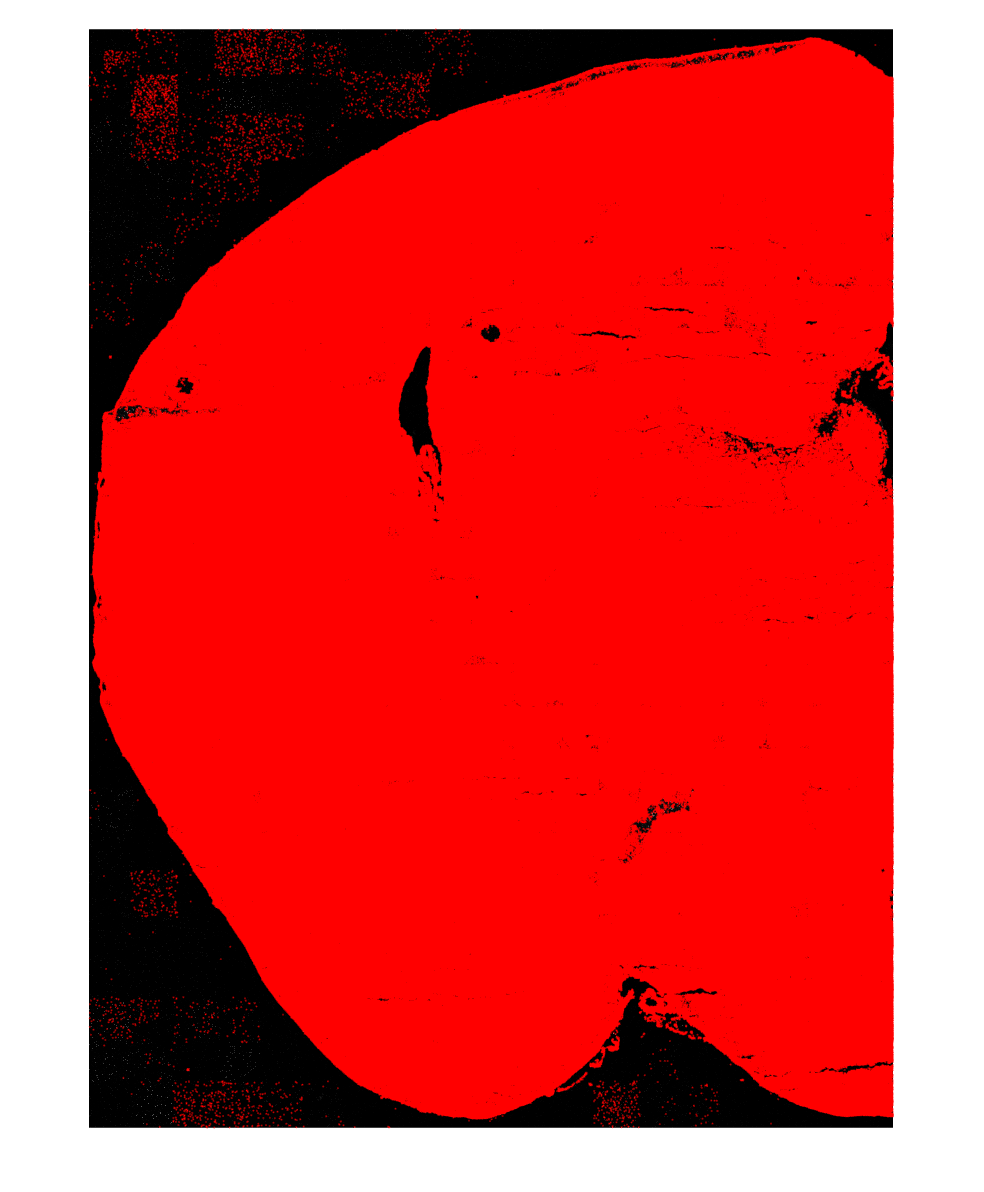


plot_centroids(merged_points, dapi_max, 1)


fname = fullfile('F:/2021-02-10-Hailing-Mouse-CNS', 'genes.csv');
f = readmatrix(fname, 'OutputType', 'string', "Delimiter", ',');
geneTonum = containers.Map(f(:,1), 1:size(f,1));
a = keys(geneTonum);
b = values(geneTonum);
merged_num = cellfun(@(x) geneTonum(x), merged_reads);

save(fullfile(input_path, 'merged_goodPoints_max3d.mat'), "merged_points", "merged_num");

plot_centroids(merged_points, dapi_max, .1)

label_path = fullfile(input_path, "stitched_images/dapi_label.tif");
label_img = new_LoadMultipageTiff(label_path, 'uint16', 'uint16', false);
figure
imshow(label_img)

save(fullfile(input_path, 'merged_goodPoints_max3d.mat'), "merged_points", "merged_num");

plot_centroids(merged_points, label_img, .1)

## test

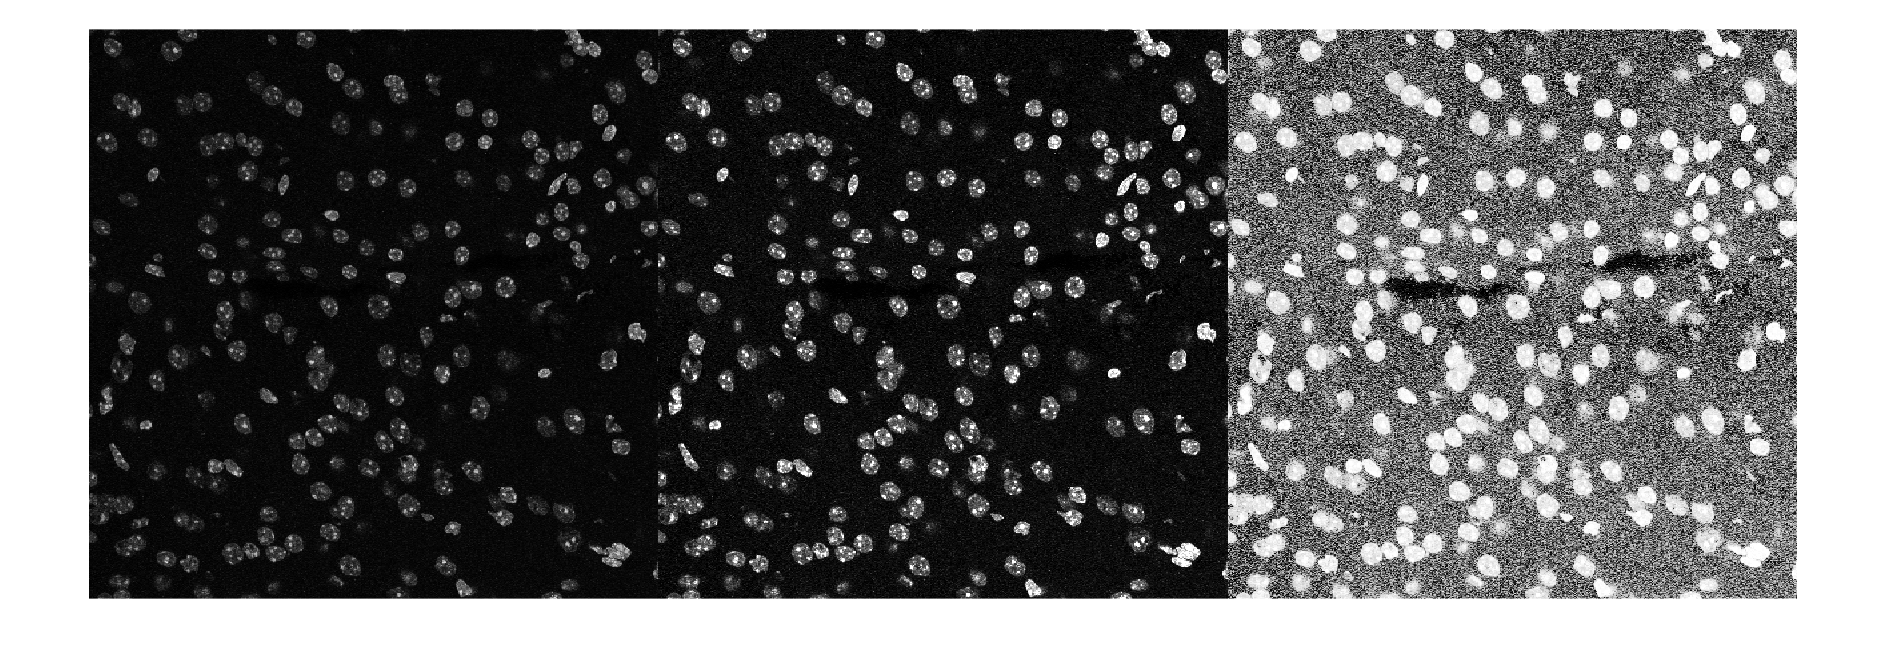

img = imread(fullfile('F:\2021-02-10-Hailing-Mouse-CNS\output\max\dapi_max_rotated\tile_111.tif'));

aimg = imadjust(img);
bimg = histeq(img);
montage({img,aimg,bimg},'Size',[1 3])